clc
clear all
close all


# ELABORATO SERVOSYSTEMS & ROBOTICS

Link's dimentions expressed in meters:

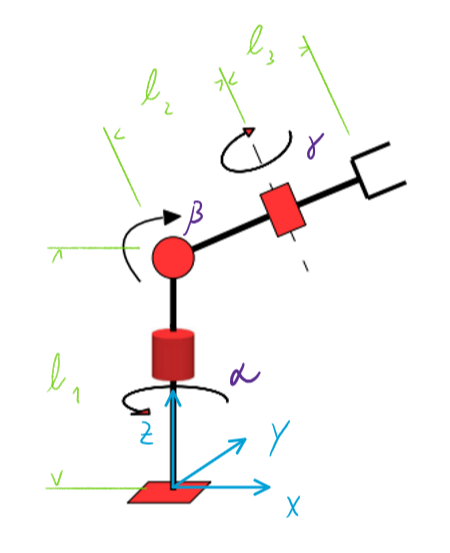

- Length of **Link 1**:

l1 = 12;

Link1 has a **Revolute Joint **that can freely rotate around the $z$ axis. $\alpha =\left\lbrack 0;\;2\pi \right\rbrack \ldotp$

- Length of **Link 2**:

l2 = 7;

Link2 has a **Revolute Joint **that can freely rotate in planes $y\;z$. $\beta =\left\lbrack 0;\;2\pi \right\rbrack$*. *

- Length of **Link 3**:

l3 = 4;

Link3 has a **Revolute Joint **that can freely rotate based on second link. $\gamma =\left\lbrack 0;\;2\pi \right\rbrack$.

L = [l1, l2, l3];

        ** 2.  KINEMATICS & DYNAMICS**:

- Kinematics data:

L = [l1; l2; l3];    % matrice link

- Direct kinematic configuration:

Qi = [0, 0, 0]';
Qf = [0.5337, -0.3913, -0.2426]';

T = 5;
n = 500;
dT = T/n;
dQ = Qf-Qi;

- Direct kinematic angular Speed Matrixes:

Lry= [0, 0, 1, 0;
      0, 0, 0, 0;
     -1, 0, 0, 0;
      0, 0, 0, 0];

Lrz=[0,-1, 0, 0;
     1, 0, 0, 0;
     0, 0, 0, 0;
     0, 0, 0, 0];

***DYNAMICS DATA***

- External forces:

Fx = 1;
Fy = 1;
Fz = 1;

F_ext = [0,  0,  0,  Fx;
         0,  0,  0,  Fy;
         0,  0,  0,  Fz;
        -Fx,-Fy,-Fz, 0];

Hg = zeros(4); 
Hg(3,4) = -9.81;

- Centri di gravità:

g1 = 5;
g2 = 2.5;
g3 = 1;

G = [g1 g2 g3 1];

- Masse e inerzie:

m1 = 11;
m2 = 7;
m3 = 4;

Jx = [0 0 0];
Jy = [0.427 0.286 0.0533];
Jz = [0.427 0.286 0.0533];

Jg = [0.427 0.286 0.0533];
Jxy = 0; Jxz = 0; Jyz = 0;

- Martrici Momenti di inerzia:

J1 = [Jx(1) Jxy Jxz;
      Jxy Jy(1) Jyz;
      Jxz Jyz Jz(1)];

J2 = [Jx(2) Jxy Jxz;
      Jxy Jy(2) Jyz;
      Jxz Jyz Jz(2)];

J3 = [Jx(3) Jxy Jxz;
      Jxy Jy(3) Jyz;
      Jxz Jyz Jz(3)];
  

- Shift Matrixes:

M1_1 = [1, 0, 0, -(l1-g1);
        0, 1, 0, 0;
        0, 0, 1, 0;
        0, 0, 0, 1];

M2_2 = [1, 0, 0, -(l2-g2);
        0, 1, 0, 0;
        0, 0, 1, 0;
        0, 0, 0, 1];

M3_3 = [1, 0, 0, -(l3-g3);
        0, 1, 0, 0;
        0, 0, 1, 0;
        0, 0, 0, 1];

- Pseudo insertia matrixes:

J1_1 = pseudoInertia(J1,m1);
J11 = M1_1*J1_1*M1_1';

J2_2 = pseudoInertia(J2,m2);
J22 = M2_2*J2_2*M2_2';

J3_3 = pseudoInertia(J3,m3);
J33 = M3_3*J3_3*M3_3';

- Transizione Velocità da giunti angolari a cartesiano:

S = [];
Sp = [];
Spp = [];

- Dynamic Evaluation:

J11_0 = [];
J22_0 = [];
J33_0 = [];

FF1 = [];
FF2 = [];
FF3 = [];

F_ext_0 = [];

EK_tot = [];
EP_tot = [];

CC1 = [];
CC2 = [];
CC3 = [];

WW1 = [];
WW2 = [];
WW3 = [];
WW4 = [];
WW_tot = [];

Q = [];
Qp = [];
Qpp = [];

***DIRECT KINEMATICS:***

for i = 1:n   
    t=(i-1)*T/(n-1);      % time from 0 to T with step dT
    tt(i)=t;
    [a(i),ap(i),app(i)] = cycloidLaw(t,T,Qi(1),dQ(1));
    [b(i),bp(i),bpp(i)] = cycloidLaw(t,T,Qi(2),dQ(2));
    [c(i),cp(i),cpp(i)] = cycloidLaw(t,T,Qi(3),dQ(3));
    
    q = [a(i);b(i);c(i)];
    qp = [ap(i);bp(i);cp(i)];
    qpp = [app(i);bpp(i);cpp(i)];
    
    Q = [Q q];
    Qp = [Qp qp];
    Qpp = [Qpp qpp];
    
    [s,M01,M12,M23] = Rotation_Matrixes_AAA(q,L); 
    
    S = [S s];
    
    M02 = M01*M12;
    M03 = M02*M23;
    
    % In generale Hij_k significa accelerazione di (j) rispetto ad (i) vista dal sistema 
    % (k)  (in maniera analoga anche per le velocità)

- Speed Evaluation:

    w01_0 = Lrz*qp(1);      % speed in 0-1 seen by the referece system 0
    w12_0 = M01*Lry*qp(2)*inv(M01);     % speed in 1-2 seen by the referece system 0
    w23_0 = M02*Lrz*qp(3)*inv(M02);     % speed in 2-3 seen by the referece system 0
    
    w02_0 = w01_0 + w12_0;      % speed in 0-2 seen by the referece system 0 (sum of speed 0-1 % 1-2)
    w03_0 = w02_0 + w23_0;      % speed in 0-3 (gripper total speed) seen by the referece system 0 (sum of speed 0-2 % 2-3)
    
    sp = w03_0*s;       % linear speed of gripper is angular velocity multiplied by s.
    Sp = [Sp sp];

- Acceleration Evaluation:

    h01_0 = (Lrz*qpp(1) + Lrz^2*qp(1)^2);       % acceleration in 0-1 seen by the referece system 0
    h12_0 = M01*(Lry*qpp(2) + Lry^2*qp(2)^2)*inv(M01);      % acceleration in 1-2 seen by the referece system 0
    h23_0 = M02*(Lrz*qpp(3) + Lrz^2*qp(3)^2)*inv(M02);      % acceleration in 2-3 seen by the referece system 0
    
    h02_0 = h01_0 + h12_0 + 2*w01_0*w12_0;      % acc in 0-2 seen by the referece system 0 (sum of acc 0-1 % 1-2 and coriolis between them)
    h03_0 = h02_0 + h23_0 + 2*w02_0*w23_0;      % acc in 0-3 seen by the referece system 0 (sum of acc 0-2 % 2-3 and coriolis between them)
    
    spp = h03_0*s;
    Spp = [Spp spp];

***DYNAMICS EVALUATION:***

    j11_0 = M01*J11*M01';
    j22_0 = M02*J22*M02';
    j33_0 = M03*J33*M03';
    
    J11_0 = [J11_0 j11_0];
    J22_0 = [J22_0 j22_0];
    J33_0 = [J33_0 j33_0];
    
    
    ff1i = -(h01_0*j11_0 - j11_0*h01_0');
    ff2i = -(h02_0*j22_0 - j22_0*h02_0');
    ff3i = -(h03_0*j33_0 - j33_0*h03_0');
    
    ff1g = Hg*j11_0 - j11_0*Hg';
    ff2g = Hg*j22_0 - j22_0*Hg';
    ff3g = Hg*j33_0 - j33_0*Hg';
    
    
    M0a = eye(4,4);
    M0a(:,4) = M03(:,4); 
    fext_0 = M0a*F_ext*M0a'; 

    ff3 = ff3i+ff3g+fext_0;
    ff2 = ff2i+ff2g+ff3;
    ff1 = ff1i+ff1g+ff2; 
    
    FF1 = [FF1 ff1];
    FF2 = [FF2 ff2];
    FF3 = [FF3 ff3];
    
    F_ext_0 = [F_ext_0 fext_0];

- Kinematic Energy:

    ek1 = trace(1/2*w01_0*j11_0*w01_0');
    ek2 = trace(1/2*w02_0*j22_0*w02_0');
    ek3 = trace(1/2*w03_0*j33_0*w03_0');
    
    ek_tot = ek1 + ek2 + ek3;
    
    EK_tot = [EK_tot ek_tot];

- Potential Energy:

    ep1 = -trace(Hg*j11_0);
    ep2 = -trace(Hg*j22_0);
    ep3 = -trace(Hg*j33_0);

    ep_tot = ep1 + ep2 + ep3;
    
    EP_tot = [EP_tot ep_tot];

- Torque of Forces:

    L12_0 = M01*Lry*inv(M01); 
    L23_0 = M02*Lrz*inv(M02); 
    
    cc1 = -PseDot(ff1,Lrz);
    cc2 = -PseDot(ff2,L12_0); 
    cc3 = -PseDot(ff3,L23_0); 
    
    CC1 = [CC1 cc1];
    CC2 = [CC2 cc2];
    CC3 = [CC3 cc3];

- Power of Forces:

    ww1 = -PseDot(ff1,w01_0);
    ww2 = -PseDot(ff2,w12_0);
    ww3 = -PseDot(ff3,w23_0);
    ww4 = PseDot(fext_0,w03_0);
    ww_tot = ww1+ww2+ww3+ww4;
    
    www1(i) = cc1*qp(1); 
    www2(i) = cc2*qp(2); 
    www3(i) = cc3*qp(3); 
    www_tot2(i) = www1(i)+www2(i)+www3(i)+ww4; 
    
    WW1 = [WW1 ww1];
    WW2 = [WW2 ww2];
    WW3 = [WW3 ww3];
    WW4 = [WW4 ww4];
    WW_tot = [WW_tot ww_tot];


end



- Total Energy:

E_tot = EK_tot + EP_tot;

- Total theoretical diff of power: for debug

P_tot = theorethicalDiff(E_tot,dT);

** 2.1 PLOT**:

- Plot configurations:

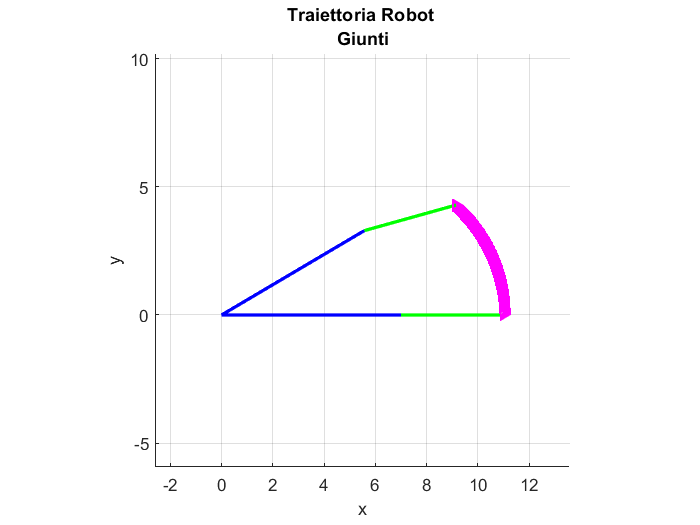

% Dati da cinematica diretta:
Plot_Trajectory_AAA(Qi,Qf,L,S(1,:),S(2,:),S(3,:),n,"Giunti");

- Plot graph of data x,y,z position speed and acceleration direct kinematics:

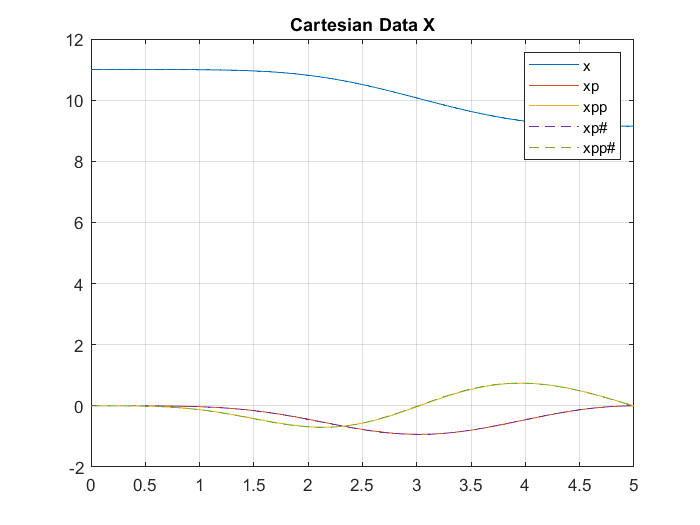

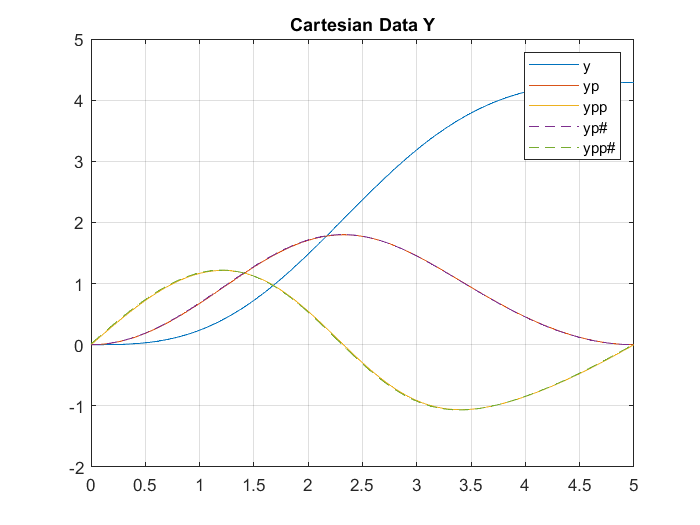

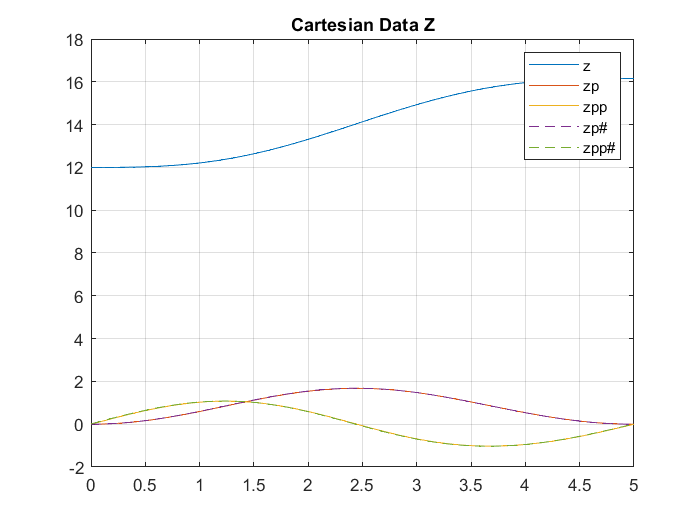

Plot_Graphs_Dir_Kinematics_AAA(S,Sp,Spp,tt,dT)

- Plot Coppie:

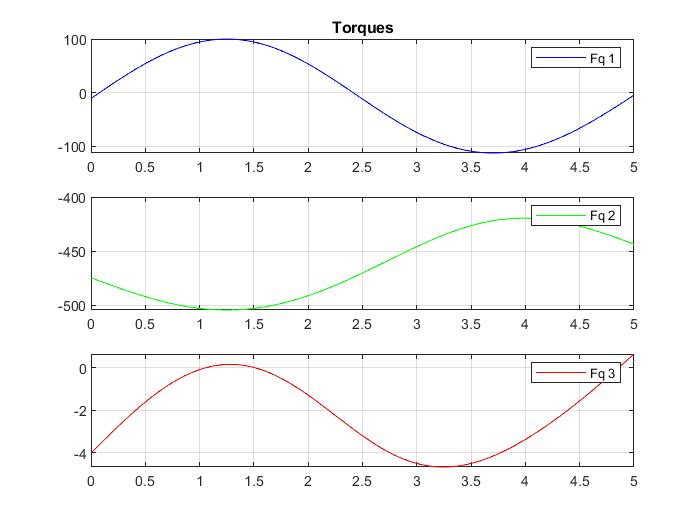

h = figure;
set(h,'name','torques')
subplot(3,1,1)
plot(tt,CC1,'b')
legend("Fq 1")
grid on
title("Torques")

subplot(3,1,2)
plot(tt,CC2,'g')
legend("Fq 2")
grid on

subplot(3,1,3)
plot(tt,CC3,'r')
legend("Fq 3")
grid on

- Plot Energia:

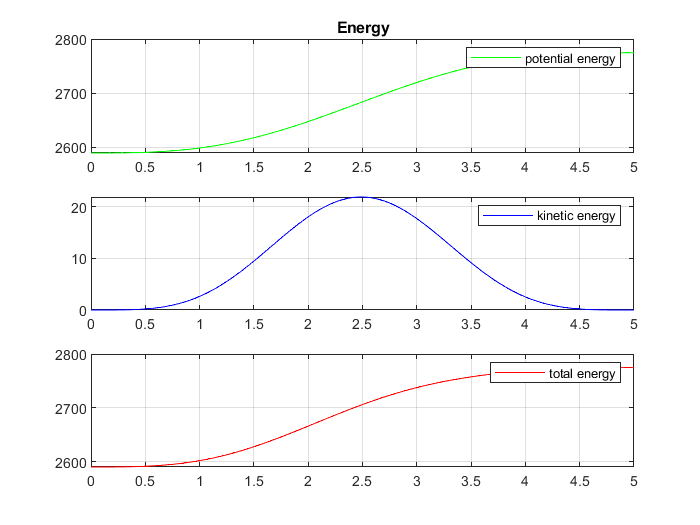

h = figure;
set(h,'name','energy') 

subplot(3,1,1)
plot(tt,EP_tot,'g')
legend("potential energy")
grid on
title("Energy")

subplot(3,1,2)
plot(tt,EK_tot,'b')
legend("kinetic energy")
grid on

subplot(3,1,3)
plot(tt,E_tot,'r')
legend("total energy")
grid on

- Plot Potenze reali e teoriche:

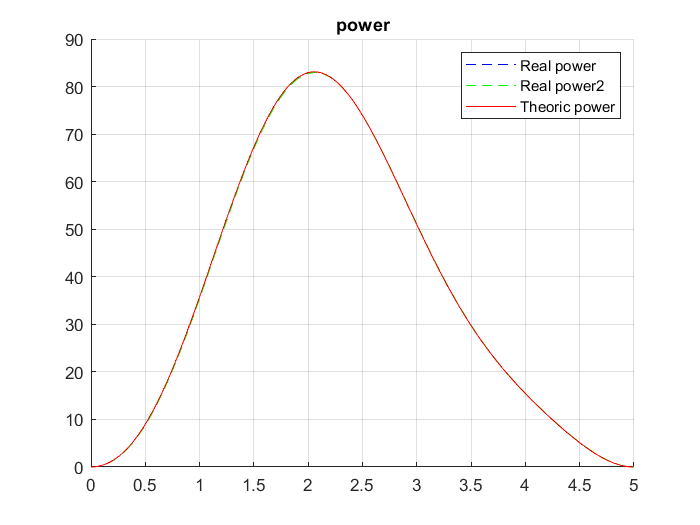

h = figure;
set(h,'name','power') 
hold on
grid on
plot(tt,WW_tot,'b--')
plot(tt,www_tot2,'g--')

plot(tt(1:length(P_tot)),P_tot,'r')
legend("Real power", "Real power2", "Theoric power")
title("power")

- Plot tutte le potenze:

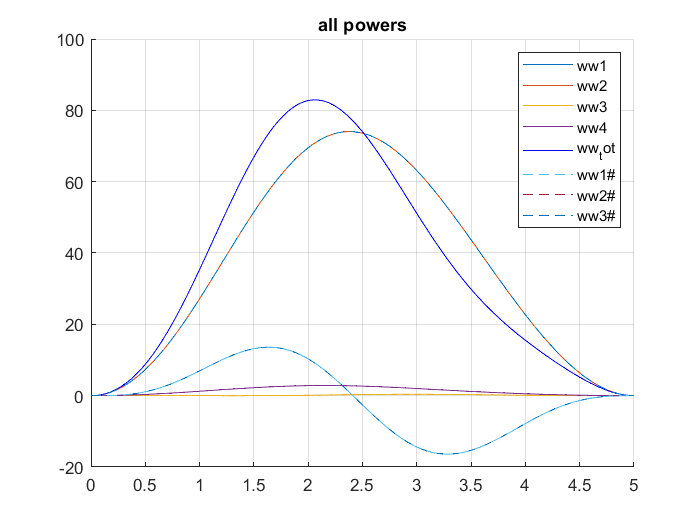

h = figure;
set(h,'name','all power') 

hold on
grid on

plot(tt,WW1)
plot(tt,WW2)
plot(tt,WW3)
plot(tt,WW4)
plot(tt,WW_tot,'b')

plot(tt,www1,'--')
plot(tt,www2,'--')
plot(tt,www2,'--')

legend("ww1","ww2","ww3","ww4","ww_tot","ww1#","ww2#","ww3#")
title("all powers")


save dati1 Q Qp Qpp S Sp Spp CC1 CC2 CC3 EP_tot EK_tot E_tot WW_tot P_tot tt